# Code Example

Any Code using this api needs to start by creating an instance of the api class of the spctrnWrp package.

The apiMemory argument specifies on how much memory will be allocated by the call of the api initialisation.

import spctrnWrp.*
A = api(apiMemory.medium)

A =   api with properties:

    deviceHandles: {}

Although it should not be a problem anymore, it is advised to only initialise one instance of the api class whenever you are using the matlab interface.

**Using the SpectranV6 follows three steps:**

    1)    Open the device. Add the device to the previously instanciated api object.When using multiple devices each will have an index starting at 0. (Probably in the same order as they are in the device manager)

deviceIndex = 0;
A.openDevice(deviceIndex, deviceTypes.iqReceiver)
disp(A)

  api with properties:

    deviceHandles: {[0]  [1×1 clib.spctrnWrp.AARTSAAPI_Device]  ["spectranv6/iqreceiver"]}


    2)    Configure the device settings (optional).

config = A.getConfigTree(deviceIndex)

config =   dynamicConfig with properties:

         device: [1×1 struct]
           main: [1×1 struct]
    calibration: [1×1 struct]

config.main.centerfreq = 2.5e9; % Copy, not reference of config
config.device.receiverchannel = spctrnWrp.deviceChannels.iqRX1;
A.setConfigTree(deviceIndex, config);

    3)    Start device and grab data. Use *getPacket *to receive a single packet for testing purposes.

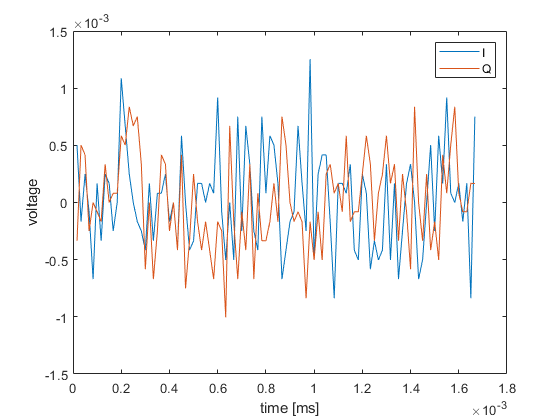

A.startDevice(deviceIndex);
P = A.getPacket(deviceIndex, config.device.receiverchannel);
plot((1:100) * (1000 / P.stepFrequency),P.fp32(1:100, :))
ylabel('voltage')
xlabel('time [ms]')
legend(["I", "Q"])

Use [stopDevice](matlab:help('spctrnWrp.api.stopDevice')) to stop device for changing settings, etc. and use *closeDevice *if you are done using it. Clearing the api object  will also close any devices previously opened.

**Carefull: **The "receiverchannel" property is not the same as the "channel" argument used for the data transport. see also: [deviceChannels](matlab:help('spctrnWrp.deviceChannels')), [configExplained](matlab:help('spctrnWrp.configExplained'))

A.stopDevice(deviceIndex);
A.setConfig(deviceIndex, "device/receiverchannel", "Rx2");
config = A.getConfigTree(deviceIndex);

Use the [getData](matlab:help('spctrnWrp.api.getData')) method to save multiple samples to a *.mat* file.

A.startDevice(deviceIndex);
A.getData(deviceIndex, spctrnWrp.deviceChannels.iqRX2, 0, 90e6, 1e6);
load('spectranData')

**Carefull: **P is a shallow copy and its data will be deallocated together with the corresponding device. Accessing P after [closeDevice](matlab:help('spctrnWrp.api.closeDevice')) has been used may lead to MATLAB chrashing! This does not apply to data stored using the [getData](matlab:help('spctrnWrp.api.getData')) method.

A.closeDevice(deviceIndex);
clear P;

**More information on all api functions under: **[Api](matlab:help('spctrnWrp.api'))

`Missing files can be found in ".\src" or at the location the "Aaronia RTSA Suite Pro" is installed.`

If you want to further build upon this api, or fix a bug, you can do this on multiple levels by:

- Changing the Matlab code contained in the "spctrnWrp" package

- Changing the implementation of the "spctrnWrp.dll" functions, which can be found in the "src" folder inside the VS-Project folder of the same name in ".\src\spctrnWrp\spctrnWrp\spctrnWrp.cpp".

- Implementing new functions for the "spctrnWrp.dll". When doing so, the Matlab Interface has to be rebuild (this is not the case if only the implementation changes but the function signature stays the same). More information on how this is done can be found in ".\+spctrnWrp\makeLibrary".